# Punto 4

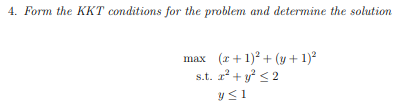

Las condiciones de optimización de KKT requieren que el gradiente de L con respecto a las variables x e y sea cero.

Estas condiciones nos permiten resolver un sistema de ecuaciones que incluye las restricciones g1 y g2. Al resolver este sistema, encontramos las soluciones que cumplen con las condiciones impuestas por las restricciones.

syms x y mu1 mu2

% Definir la función objetivo
f = (x + 1)^2 + (y + 1)^2;
fun=matlabFunction(f)

fun = function_handle with value:
    @(x,y)(x+1.0).^2+(y+1.0).^2


% Definir las restricciones
g1 = x^2 + y^2 - 2;  % Restricción de la circunferencia
g2 = y - 1;           % Restricción de la desigualdad y <= 1

% Función Lagrangiana
L = f + mu1*g1 + mu2*g2

$$L = {\left(x+1\right)}^{2}+{\left(y+1\right)}^{2}+\mu_{2}\,\left(y-1\right)+\mu_{1}\,\left(x^{2}+y^{2}-2\right)$$


% Calcular las derivadas parciales de Lagrangiana
disp('Primera condición KKT (gradiente de L):');

Primera condición KKT (gradiente de L):


grad_L = gradient(L, [x,y])

$$grad\_L = \left(\begin{array}{c} 2\,x+2\,\mu_{1}\,x+2\\ \mu_{2}+2\,y+2\,\mu_{1}\,y+2 \end{array}\right)$$


% Resolver las ecuaciones del gradiente respecto a x_i
eq1 = grad_L == 0

$$eq1 = \left(\begin{array}{c} 2\,x+2\,\mu_{1}\,x+2=0\\ \mu_{2}+2\,y+2\,\mu_{1}\,y+2=0 \end{array}\right)$$


% Impongo las restricciones
eq2 = g1 == 0;
eq3 = g2 == 0;

% Resolver el sistema de ecuaciones
disp('Resolviendo el sistema KKT...');

Resolviendo el sistema KKT...


vars = [x;y; mu1; mu2]; 
solutions = solve([eq1; eq2; eq3], vars, 'Real', true);

% Mostrar las soluciones
disp('Soluciones para x, y, mu1 y mu2:');

Soluciones para x, y, mu1 y mu2:


solutions_x = solutions.x;
solutions_y = solutions.y;
mu1_sol = (solutions.mu1);
mu2_sol = (solutions.mu2);

disp('Soluciones de x:');

Soluciones de x:


disp(solutions_x);

$$\left(\begin{array}{c} 1\\ -1 \end{array}\right)$$


disp('Soluciones de y:');

Soluciones de y:


disp(solutions_y);

$$\left(\begin{array}{c} 1\\ 1 \end{array}\right)$$


disp('Valor de mu1:');

Valor de mu1:


disp(mu1_sol);

$$\left(\begin{array}{c} -2\\ 0 \end{array}\right)$$


disp('Valor de mu2:');

Valor de mu2:


disp(mu2_sol);

$$\left(\begin{array}{c} 0\\ -4 \end{array}\right)$$

La Hessiana del Lagrangiano se utiliza para determinar si este punto es un máximo local. Al evaluar los valores propios de la Hessiana, encontramos que todos son positivos, indicando que (1,1) es un mínimo local de f(x,y) dentro del conjunto factible.

% Segunda condición KKT: Hessiana del Lagrangiano respecto a x
disp('Hessiana del Lagrangiano:');

Hessiana del Lagrangiano:


Hessian_L = hessian(L, [x,y]);
disp(Hessian_L);

$$\left(\begin{array}{cc} 2\,\mu_{1}+2 & 0\\ 0 & 2\,\mu_{1}+2 \end{array}\right)$$

ValoresPro=eig(Hessian_L)

$$ValoresPro = \left(\begin{array}{c} 2\,\mu_{1}+2\\ 2\,\mu_{1}+2 \end{array}\right)$$


i=0;
for i = 1:length(solutions.mu1)
    ValoresPro2=subs(ValoresPro,[x,y,mu1,mu2],[solutions.x(i), solutions.y(i), solutions.mu1(i), solutions.mu2(i)])
    % Clasificar según los valores propios
    if all(ValoresPro2 > 0)
        disp('La solución corresponde a un MÍNIMO local.');
    elseif all(ValoresPro2 < 0)
        disp('La solución corresponde a un MÁXIMO local.');
    else
        disp('La solución corresponde a un PUNTO SILLA.');
    end
    i=i+1;
end

$$ValoresPro2 = \left(\begin{array}{c} -2\\ -2 \end{array}\right)$$

La solución corresponde a un MÁXIMO local.


$$ValoresPro2 = \left(\begin{array}{c} 2\\ 2 \end{array}\right)$$

La solución corresponde a un MÍNIMO local.


% Verificación de las restricciones para cada solución
for i = 1:size(solutions_x, 1)
    current_solution = double(solutions_x(i, :));
    current_solution2 = double(solutions_y(i, :));
    g1_val = (current_solution)^2 + (current_solution2)^2 - 2;  % Restricción de la circunferencia
    g2_val = (current_solution2) - 1;

    disp(['Solución ', num2str(i), ':']);
    disp(g1_val);
    disp(g2_val);
end

Solución 1:


     0



     0



Solución 2:


     0



     0



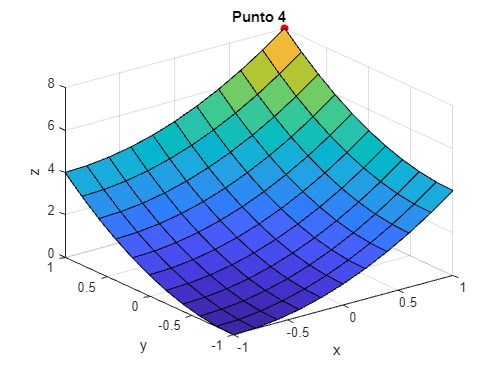


%%%  Visualización
x = -1:.2:1;
y = -1:.2:1;
[X,Y] = meshgrid(x,y);
Z = fun(X,Y);
 
surf(X,Y,Z), hold on
xlabel('x'),ylabel('y'),zlabel('z')
title('Punto 4')
scatter3(1,1,fun(1,1),'r','filled')

## Respuesta

Maximizar la función objetivo significa encontrar los valores de las variables que dan el valor más grande posible a la función f(x,y), pero respetando las restricciones impuestas, en este caso el círculo definido por x2+y2≤2 y la condición y≤1. En donde se encontro que para este problema para maximixar la función x deber ser igual a 1 y y también debe ser igual a 1.  Es el punto óptimo que maximiza la función objetivo dentro del conjunto factible.